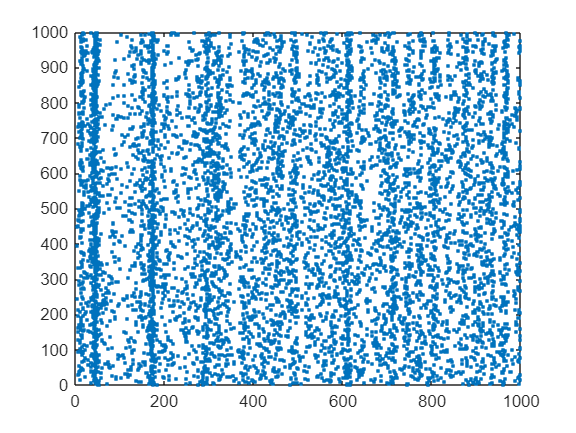

% Created by Eugene M. Izhikevich, February 25, 2003
% Excitatory neurons    Inhibitory neurons
Ne=800;                 Ni=200;
re=rand(Ne,1);          ri=rand(Ni,1);
a=[0.02*ones(Ne,1);     0.02+0.08*ri];
b=[0.2*ones(Ne,1);      0.25-0.05*ri];
c=[-65+15*re.^2;        -65*ones(Ni,1)];
d=[8-6*re.^2;           2*ones(Ni,1)];
S=[0.5*rand(Ne+Ni,Ne),  -rand(Ne+Ni,Ni)];

v=-65*ones(Ne+Ni,1);    % Initial values of v
u=b.*v;                 % Initial values of u
firings=[];             % spike timings

for t=1:1000            % simulation of 1000 ms
  I=[5*randn(Ne,1);2*randn(Ni,1)]; % thalamic input
  fired=find(v>=30);    % indices of spikes
  firings=[firings; t+0*fired,fired];
  v(fired)=c(fired);
  u(fired)=u(fired)+d(fired);
  I=I+sum(S(:,fired),2);
  v=v+0.5*(0.04*v.^2+5*v+140-u+I); % step 0.5 ms
  v=v+0.5*(0.04*v.^2+5*v+140-u+I); % for numerical
  u=u+a.*(b.*v-u);                 % stability
end;
plot(firings(:,1),firings(:,2),'.');